# Rad229_Motion_Artifacts_Demo

## Demonstrates the impact of motion on both images and k-space.

[DBE@STANFORD.EDU](mailto:DBE@STANFORD.EDU) (April 2021) for Rad229

## Define MRI system constants

sys = Rad229_MRI_sys_config;

## Set-up some default acquisition parameters

acq.Nx = 64;                            % Matrix is NxN (then padded later to accomodate motion)
acq.dt = 100e-3;                        % Time step [s]
acq.N_phs = 16;                         % Number of image phases [#]
acq.dur = acq.dt * ( acq.N_phs - 1 );   % Duration of motion [s]
acq.t = 0 : acq.dt : acq.dur;           % Time vector during motion [s]
acq.t_norm = ( 0 : acq.N_phs - 1 ) / acq.N_phs; % Normalized time vector

## Generate the phantom object

[ P , M ] = Rad229_MRI_Phantom( acq );
P = repmat( P , [ 1 1 acq.N_phs ]);  % Replicate the object in time

## Define a pulsatile "vessel" signal frequency and amplitude

% Pulse frequency [cycles / phase] (e.g. 1 is one cycle per "beat")
obj.f_p = 1.0;   

% Pulse amplitude (simulates in-flow effect) [A.U.]
obj.A_p = 2.0;   

% Identify the phantom sub-object (default phantom has 11 objects)
obj.num = 4;     

## Create pulsating "vessel" object

% Create the pulse amplitude function
obj.pulse_amp = obj.A_p * ( 1 + sin( 2 * pi * obj.f_p * acq.t_norm ) );

% Replicate "vessel" object in time
VSL = repmat( M( : , : , obj.num ) , [1 1 acq.N_phs] );

% Multiply the "vessel" object by the pulse amplitude function
VSL = VSL .* repmat( reshape( obj.pulse_amp , [ 1 1 length(obj.pulse_amp) ] ) , [acq.Nx acq.Nx 1] );

## Define the bulk motion field for the object

% Define the object's bulk motion
obj.dx_max = 0 ;  % Max x-displacement [pixels]
  warning('X-displacements not fully implemented.');

obj.dy_max = -0 ; % Max Y-displacement [pixels]
obj.f_bx = 1.0;   % Bulk frequency [cycles / phase] (e.g. 1 is one cycle per "beat")
obj.f_by = 1.0;   % Bulk frequency [cycles / phase] (e.g. 1 is one cycle per "beat")

% Define bulk motion path for each phase
obj.xt = obj.dx_max * ( sin( 2 * pi * obj.f_bx * acq.t_norm ) );
obj.yt = obj.dy_max * ( sin( 2 * pi * obj.f_by * acq.t_norm ) );

% Apply bulk motion and combine the pulsating "vessel" object with the static object
for n = 1 : acq.N_phs
  PHT( : , : , n) = circshift( P( : , : , n) + VSL( : , : , n) , round( obj.yt(n) ) , 1 );
end

## Add noise

% Note: this is an over-simplication of noise in an MRI acquisition
PHT = PHT + 0.0001 * max(PHT(:)) * randn (size (PHT) );

## Display the phantom "Motion Path"

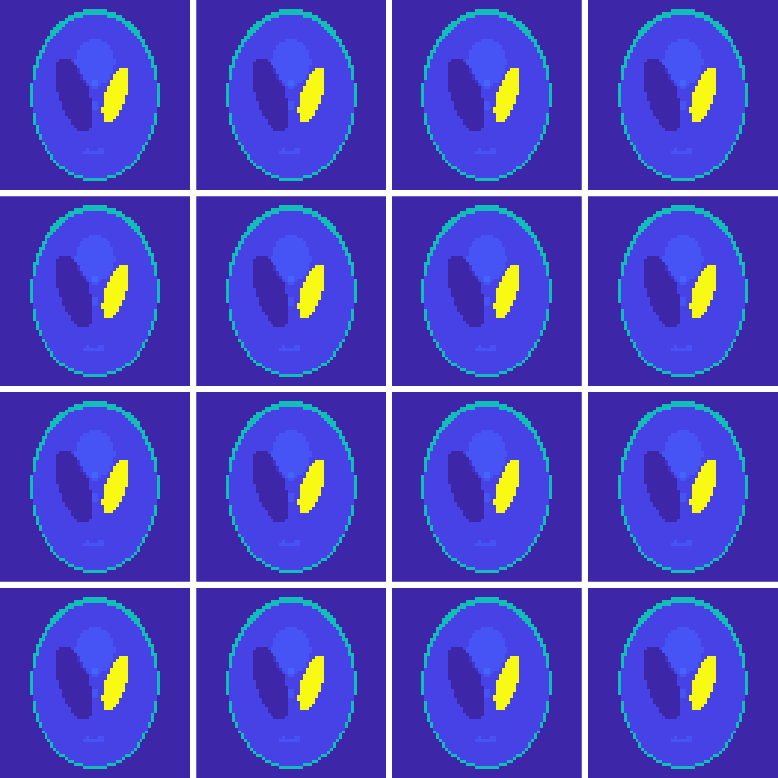

figure; imagescn(PHT);

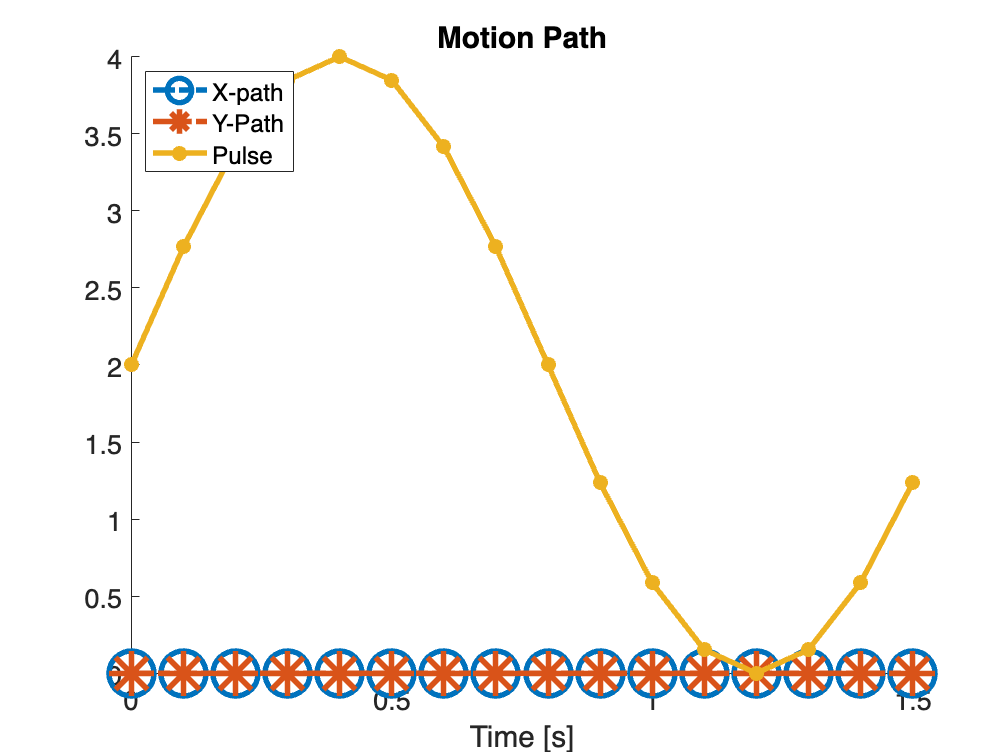


set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',15);
figure; hold on; colormap(hot);
  plot( acq.t , obj.xt , 'o-.'); 
  plot( acq.t , obj.yt , '*-.');
  plot( acq.t , obj.pulse_amp, '.-');
  title('Motion Path'); xlabel('Time [s]')
  legend('X-path','Y-Path','Pulse','Location','NorthWest');


% PHT_scl = 255 * mat2gray( abs( PHT ) ) + 1; % Scale range for IMMOVIE function
% P_mov = reshape( PHT_scl , [ size(PHT,1) size(PHT,2) 1 size(PHT,3) ] );
% mov = immovie( P_mov , hot );
%   implay(mov,4);

## Compute the k-space for each phase

kspc = complex(zeros(size(PHT)));
for n=1:acq.N_phs
  kspc(:,:,n)=fftshift(fft2(PHT(:,:,n)));
end

figure; imagescn( abs( kspc ) ); colormap( hot );

## Extract a the ky-lines acquired for each motion state (i.e. phase)

VPS = size( P , 1 ) / acq.N_phs;  % Views-per-segment (lines of k-space acquired per phase)
for m = 1 : acq.N_phs
  ind0 = 1 + ( m - 1 ) * VPS;  % Index to first ky-line
  ind1 = m * VPS;              % Index to last ky-line
  kspc_motion( ind0 : ind1 , : ) = kspc( ind0 : ind1 , : , m ); % Copy lines from the mth phase
end

% Recover the acquired image for the moving/pulsatile object
PHT_motion=ifft2( fftshift( kspc_motion ) ); % Image of moving object

## Generate figures...

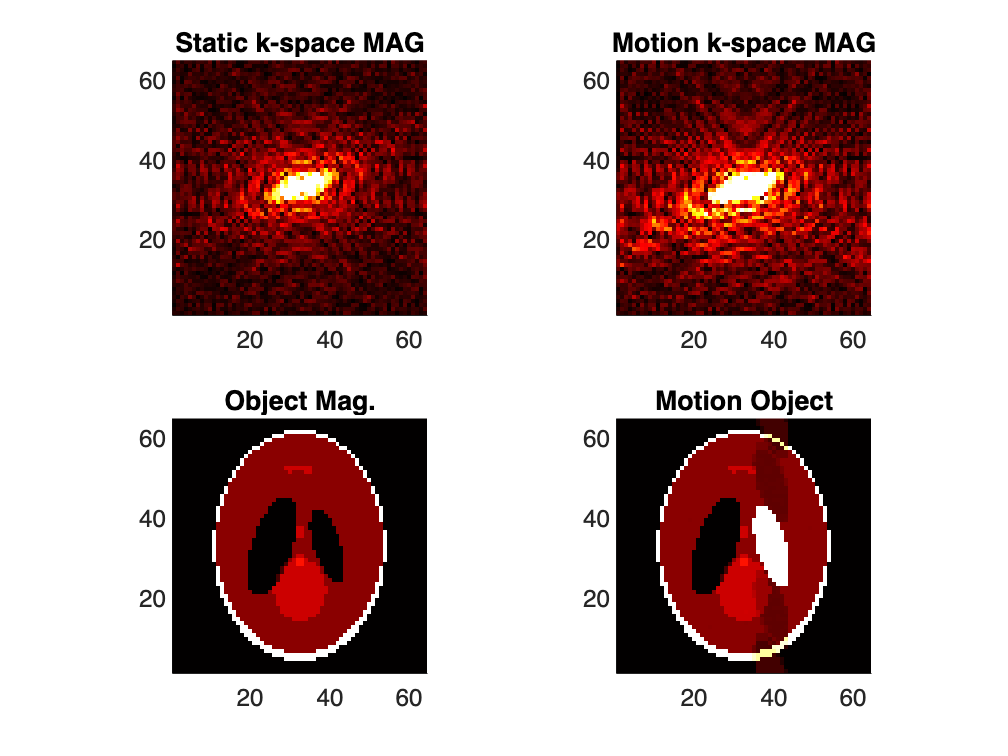

set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',15);
figure; hold on; colormap(hot);
subplot( 2 , 2 , 1 ); hold on;
  imagesc( abs( kspc( : , :, 1 ) ) ); caxis([ 0 max( abs( kspc(:) ) ) / 10 ]);
  title('Static k-space MAG'); axis equal tight;
  
subplot( 2 , 2 , 2 ); hold on;
  imagesc(abs(kspc_motion)); caxis([0 max(abs(kspc_motion(:)))/10]);
  title('Motion k-space MAG'); axis equal tight;

subplot( 2 , 2 , 3 ); hold on;
  imagesc( abs( P( : , : , 1 ) ) ); caxis( [0 1] );
  title('Object Mag.'); axis equal tight;
  
subplot( 2 , 2 , 4 ); hold on;
  imagesc( abs( PHT_motion ) ); caxis( [0 1] );
  title('Motion Object'); axis equal tight;